**Other things to do with images**

Rearranging an image - Swapping halfs

img = imread('faces.png');
[rows,cols, layers] = size(img)

rows = 500

cols = 500

layers = 3

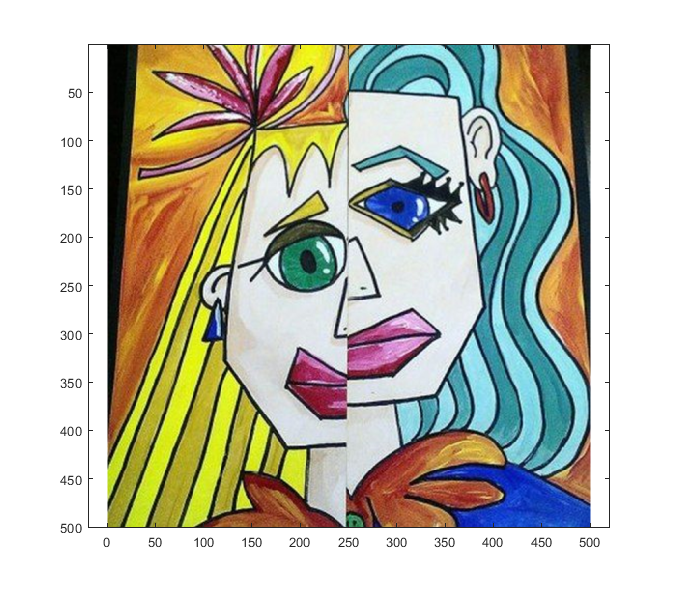


image(img);
axis on; axis equal;

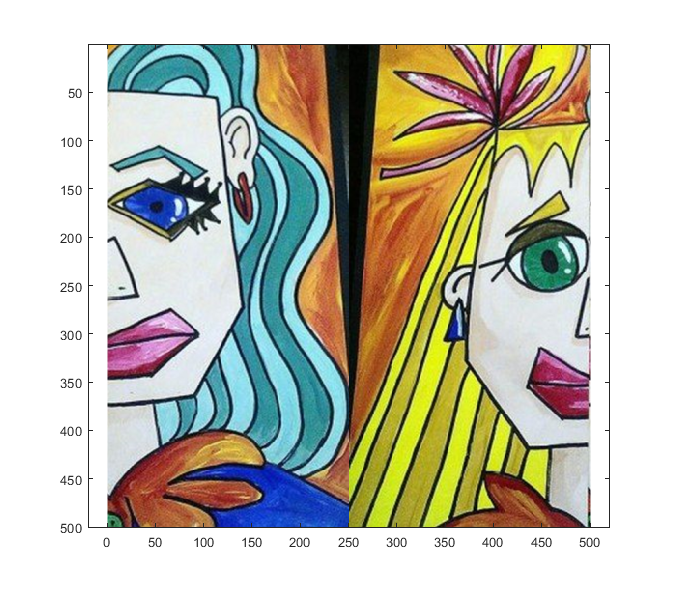


halfRows = floor(rows/2);
halfCols = floor(cols/2);
halfRowsPlus1 = halfRows+1;
halfColsPlus1 = halfCols+1;

newImg = img; %Make a copy of the original so tha the dimesnions of your new image are correct.
newImg(:, 1:halfCols, :) = img( :, halfColsPlus1:end, :); %Left of new gets Right of original
newImg(:, halfColsPlus1:end, :) = img( :, 1:halfCols, :); %Right of new gets Left of original
image(newImg);
axis on; axis equal;

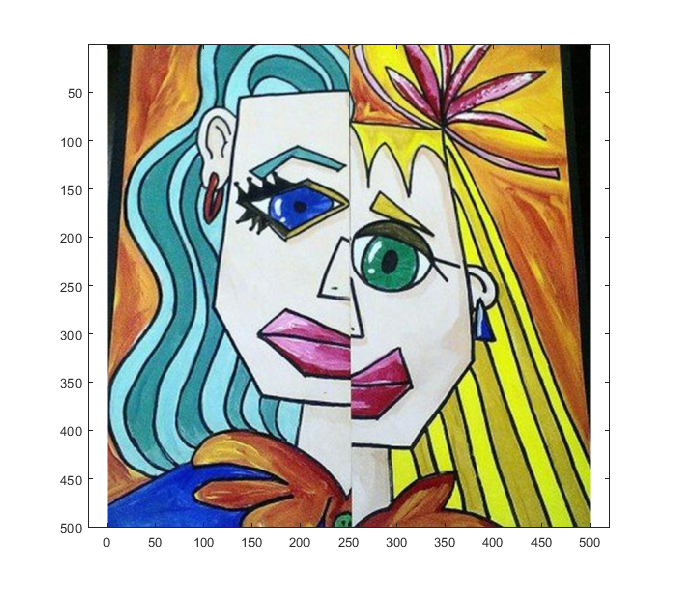


newImg(:, 1:halfCols, :) = newImg(:, halfCols:-1:1, :);
newImg(:, halfColsPlus1:end, :) = newImg(:, end:-1:halfColsPlus1, :);
image(newImg);
axis on; axis equal;

Rearranging an image - Swapping quadrants

img = imread('faces.png');
[rows,cols, layers] = size(img)

rows = 500

cols = 500

layers = 3


image(img);
axis on; axis equal;


halfRows = floor(rows/2);
halfCols = floor(cols/2);
halfRowsPlus1 = halfRows+1;
halfColsPlus1 = halfCols+1;

newImg = img; %Make a copy of the original so tha the dimesnions of your new image are correct.
newImg(1:halfRows, 1:halfCols, :) = img( halfRowsPlus1:end, halfColsPlus1:end, :); %Top Left of new gets Bottom Right of original
newImg(1:halfRows, halfColsPlus1:end, :) = img( halfRowsPlus1:end, 1:halfCols, :); %Top Right of new gets Bottom Left of original
newImg(halfRowsPlus1:end, 1:halfCols, :) = img( 1:halfRows, halfColsPlus1:end, :); %Bottom Left of new gets Top Right of original
newImg(halfRowsPlus1:end, halfColsPlus1:end, :) = img( 1:halfRows, 1:halfCols, :); %Bottom Right of new gets Top Left of original

image(newImg);
axis on; axis equal;


Image resizing and placement

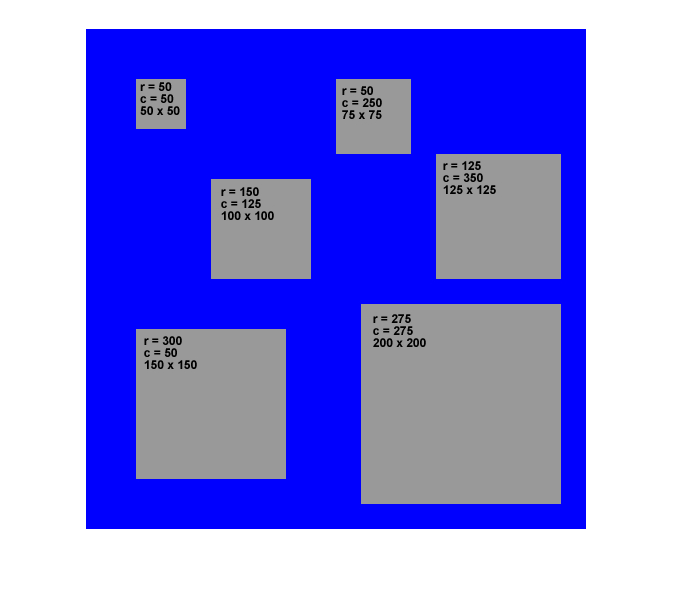

clear
clc
close all

%Import images
frame = imread('simpsonsFrame.jpg');
bart = imread('bart.jpg');
lisa = imread('lisa.jpg');
homer = imread('homer.jpg');
marge = imread('marge.jpg');
maggie = imread('maggie.jpg');
family = imread('family.jpg');

%Show frame
figure;
imshow(frame);

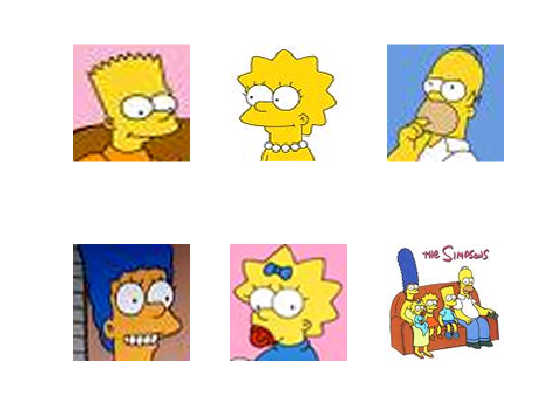


%Show pics
figure
pics = {bart, lisa, homer, marge, maggie, family};
for index = 1:length(pics)
    subplot(2,3,index);
    imshow(pics{index});
end

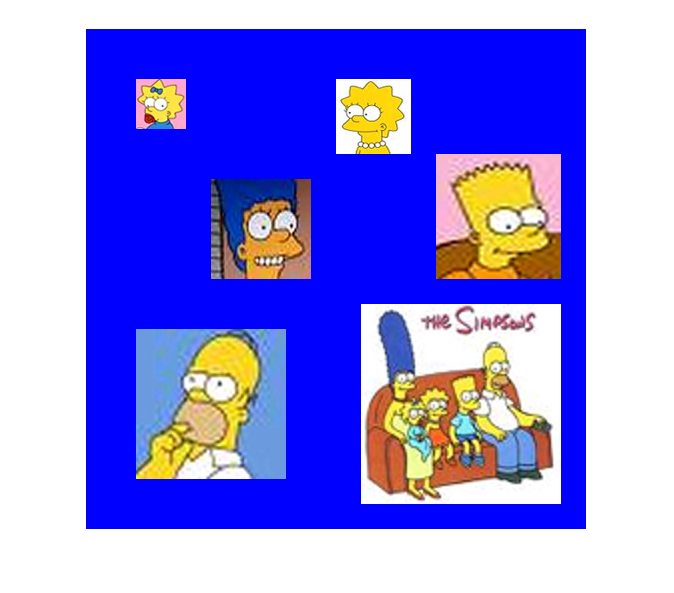

   

%Resize and paste pics into frame
figure
frame([51:100],[51:100],:) = imresize(maggie,[50, 50]);
frame([51:125],[251:325],:) = imresize(lisa,[75,75]);
frame([151:250],[126:225],:) = imresize(marge,[100,100]);
frame([126:250],[351:475],:) = imresize(bart,[125, 125]);
frame([301:450],[51:200],:) = imresize(homer, [150, 150]);
frame([276:475],[276:475],:) = imresize(family,[200,200]);

imshow(frame);